# Analysis of microRNA data in relation to their therapeutic potential

## Background

### What is miRNA?

MicroRNA (**miRNA**) is a small non-coding RNA (~20-25 nucleotides) that regulates the expression of multiple target genes. As target recognition does not require full complementarity, a single miRNA can regulate multiple messenger RNAs (mRNAs). This combined effect by a single miRNA results in significant changes that can be measured. 

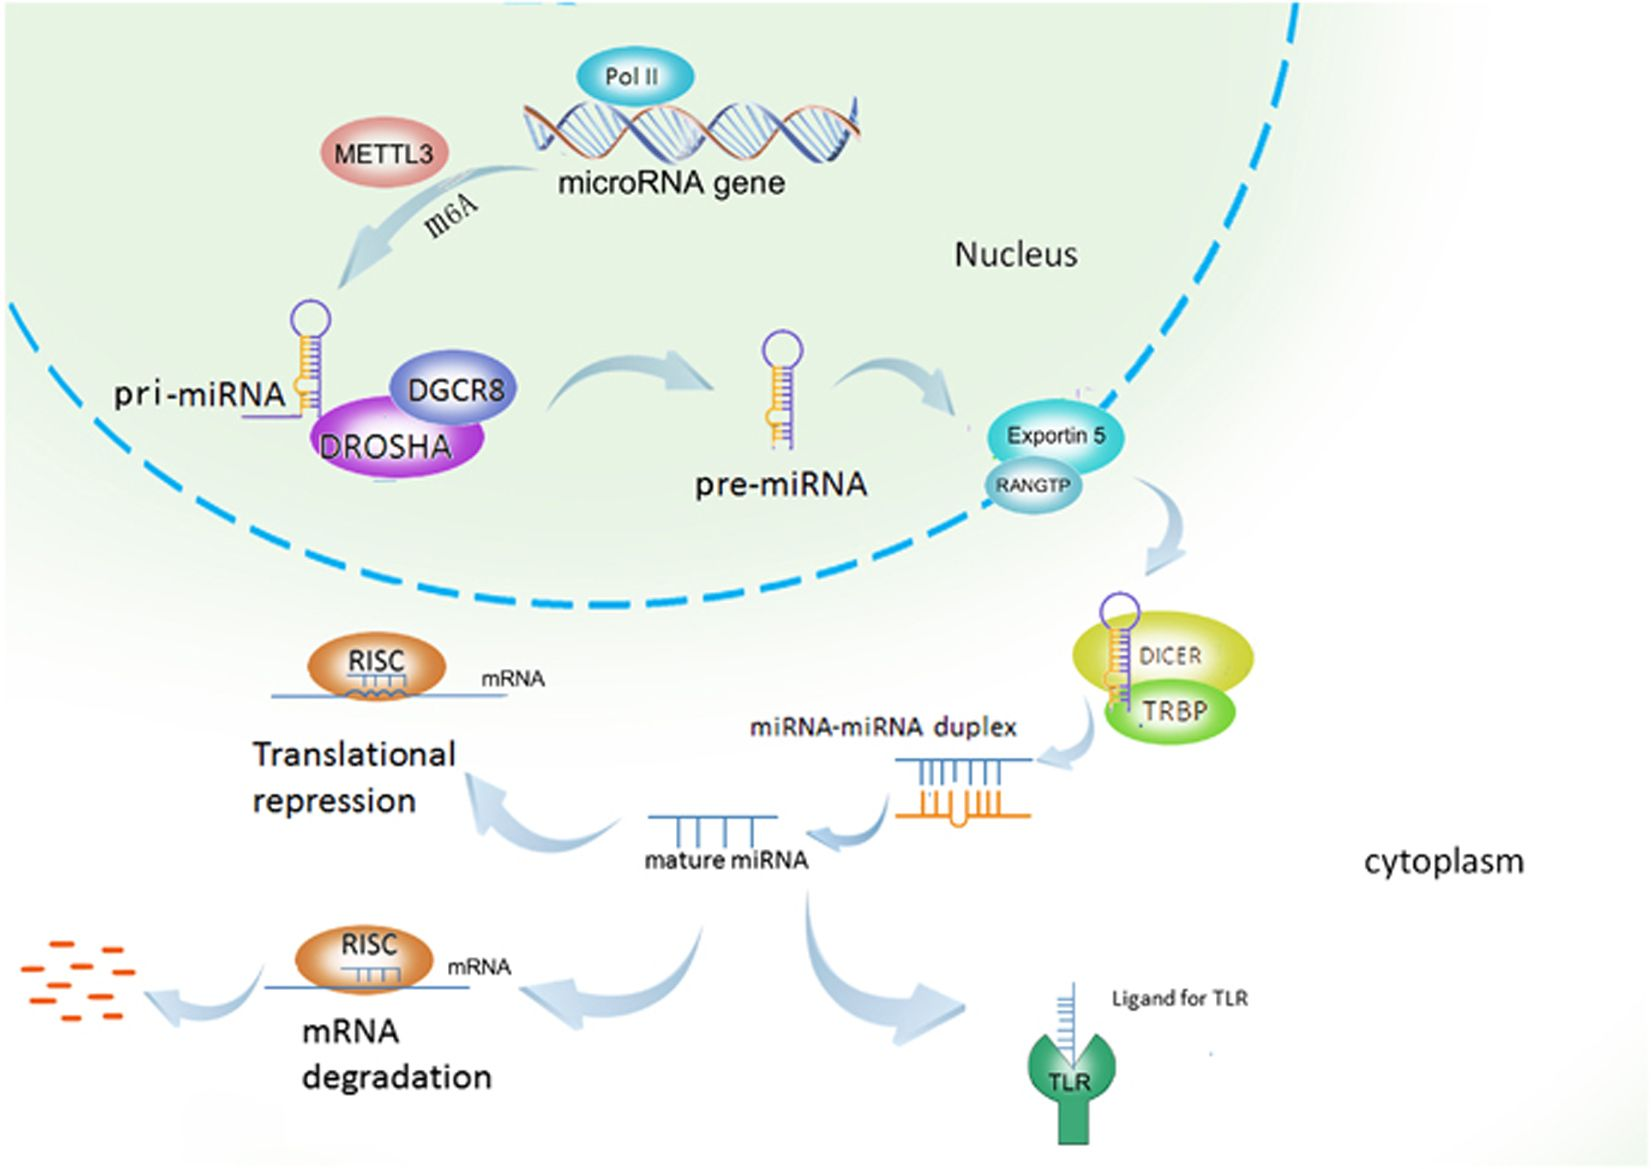

### miRNAs in Disease

Alteration in miRNA expression is associated with various diseases such as heart failure, cancer, and atherosclerosis to name a few. When a miRNA is differentially expressed in a specific disease, it is classified as a **signature miRNA** for that disease. The table below provides a list of signature miRNAs and their associated diseases: 

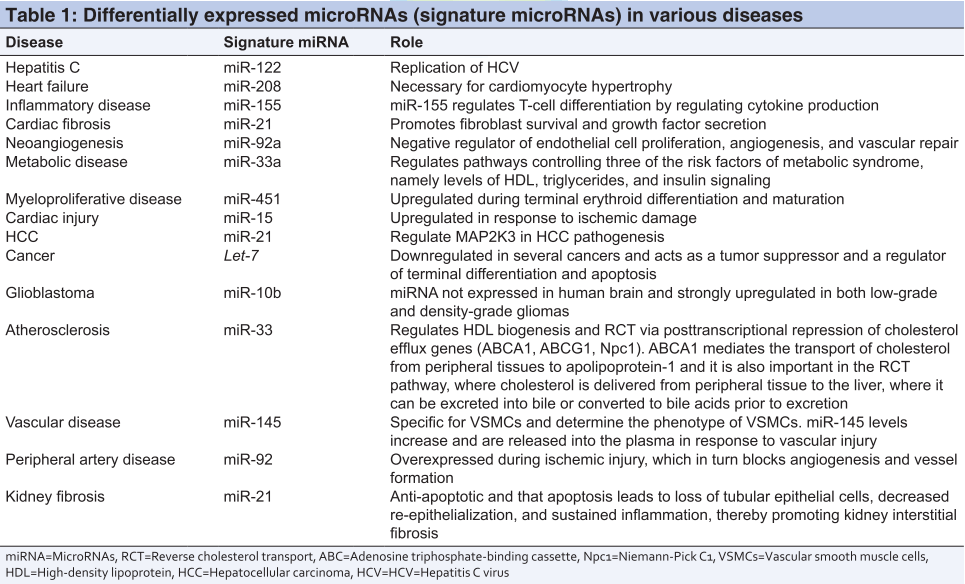

### miRNAs as Therapeutics

Due to their role in various diseases, miRNAs are being investigated as therapeutics. Similar to drug development, this process requires several steps: 

- Identify signature miRNA for disease of interest (via miRNA profiling)

- Validation of signature miRNA (via loss/gain of function studies *in vitro* and *in vivo*)

- Pharmacological analysis (via delivery studies and pharmacokinetics/pharmacodynamics)

- Clinical trials (evaluation of drug efficacy and safety)

## Exploratory Analysis of miRNA Data

For today's lecture, we will be analyzing expression levels of 18 miRNAs collected from 70 tissue samples. This dataset includes samples from both healthy and diseased individuals. Our main tasks for today will be to: 

- Determine the optimal number of clusters for this data using k-means clustering

- Visualize this data as a 2D scatter plot using principal component analysis

- Identify which disease is represented using hierarchical clustering

### Load and examine the data

To start, load the dataset (*miRNA_data.xlsx*) as a table. Based on the information provided, create a variable to store the patient IDs, a variable to store the health status for each patient, a variable to store the miRNA gene names, and a variable to store the miRNA expression data as a matrix:

% Load the dataset

% Create a variable for patient IDs

% Create a variable for patient health status

% Create a variable for gene names

% Create a variable for gene expression data


Plot a histogram for the expression data to see how it is distributed (make sure to include axis labels and a title): 

% Histogram of expression data




Questions: How is the data distributed? 

### Determine the optimal k value using k-means clustering

Use k-means clustering to quantitatively determine the best estimate for how many clusters the data separates into. For this task, create a for-loop to calculate the silhouette statistic for k values ranging from 2 to 10. Below is a base template to help you get started (you'll only need to modify the parts in curly brackets): 

% Create a vector of k values ranging from 2 to 10
{vector of k values}

% For-loop to calculate the silhouette statistic for different k values
n = length({vector of k values});   % number of k values
s_statistic = zeros(n,1);           % variable to store silhouette statistic values
for i = 1:n
    % Use the kmeans function to cluster patients into k clusters
    [idx,~] = kmeans({miRNA expression data},{k value});
    % Use the silhouette function to calculate silhouette values
    s = silhouette({miRNA expression data},idx);
    % Calculate a weight value proportional to positive silhouette values
    weight = sum(s > 0)/length(s);
    % Calculate the silhouette statistic by multiplying the weight with the
    % mean of silhouette values and store this to s_statistic
    s_statistic(i) = weight*mean(s);
end

Question: What is the value for the max silhouette statistic? Which k value does this correspond with? 

Based on your answer to the question above, generate a silhouette plot:

% Silhouette plot based on best k value



Question: Are there any negative silhouette values? If so, what does this imply?

Using your variable for patient health status, assess how patients cluster based on your *idx* variable from k-means clustering: 

% Cluster patients by health status using idx variable from kmeans



Question: What do you notice from this assessment? 

### Visualize the data in lower dimension using PCA

Now we'll apply principal component analysis (PCA) to visualize our data within a lower-dimensional space (use the patient health status for labeling):

% Apply PCA to the gene expression data (use patient health status for labeling)


Question: Based on the plot of PC1 vs. PC2, how many distinct clusters can you identify? How much variance do PC1 and PC2 account for?

Question: Highlight one of the clusters you see. Does this match with one of the clusters from our k-means results?

### Identify disease represented using hierarchical clustering

Create a clustergram of the expression data, using patient health status to label the rows and the miRNA gene names to label the columns. Also be sure to standardize all values by column:

% Create clustergram (label rows, label columns, and standardize by
% columns)





Question: Based on how the rows (patients) cluster, does this match our results from k-means clustering and PCA?

Generate the clustergram again, but this time use correlation as the distance metric for both rows and columns: 

% Generate clustergram (label rows, label columns, standardize by columns, 
% and use correlation as the distance metric for both rows and columns)






Question: How did the clustering change? Does this match our results from k-means clustering and PCA?

Question: Based on the patterns seen in the clustergram, can you identify any signature miRNAs? If so, which disease(s) could be represented in our data (refer to the table below)? 